# Aplicación de métodos numéricos a un modelo presa-depredador

**Ecuaciones del modelo:**


$$\left\{\begin{array}{lll}
\dot{P} & = & \alpha P- \beta PD \\ 
\dot{D} & = & \delta PD - \gamma D
\end{array}\right.$$


con **condiciones iniciales** $P(0) =3$ y $D(0)=1$.

y **valores de parámetros** $\alpha = 2$, $\beta = 1.2$, $\delta = 1$ y $\gamma=0.9$.

Donde, P es el **número de presas** (en unidades de miles), D es el **número de depredadores** (en unidades de miles), $\alpha$ es la tasa (en año$^{-1}$ ) de** crecimiento de la presas** en ausencia de depredadores (se asume que si no hay depredadores el número de presas crecería exponencialmente), $\gamma$ es la tasa  (en año$^{-1}$ ) de** mortalidad de los depredadores** (se asume que si no hay presas el número de depredadores decrecería exponencialmente), $\beta$ es la tasa por depredador  (en año$^{-1}$ D$^{-1}$) de **interacciones exitosas** de las presas con los depredadores (un valor mayor valor implica un impacto negativo en el crecimiento del número de presas) y $\delta$ es la tase por presa (en año$^{-1}$ P$^{-1}$) de **interacciones exitosas** de los depredadores con las presas (un valor mayor valor implica un impacto positivo en el crecimiento del número de depredadores).

#### 1. Resolver numéricamente la ecuación diferencial no lineal, graficar las soluciones $P(t)$ y $D(t)$, y analizar el resultado.

close all
syms P(t) D(t)
alfa = 2; beta = 1.2; delta = 1; gamma = 0.9;           %Parámetros del modelo
f1 = alfa*P - beta*P*D; f2 = delta*P*D - gamma*D;       %Parte derecha de la ecuación de estado: x' = f(x)
f = odeFunction([f1 f2],[P D]);                         %Ecuación de estado en una forma para ser resuelta numéricamente
ci = [3 1];                                             %Condiciones iniciales numéricas (corresponde al primer tiempo en dt).En unidades de miles
Ts = 0.1;                                               %Paso de la solución numérica (probar con diferentes valores)
tmin = 0;                                               %Siempre debe ser mayor o igual que cero
tmax = 20;                                              %Tiempo máximo de la simulación
tspan = tmin:Ts:tmax;                                   %Intervalo de tiempo para graficar
[t,x] = ode45(f,tspan,ci);                              %Aplicación del método numérico de Runge-Kutta de un solo paso: x(k) se calcula a partir de x(k-1)

Respuesta temporal (soluciones en función del tiempo):

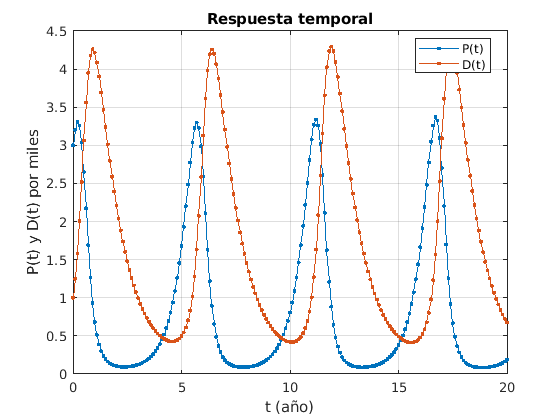

figure
plot(t,x,'.-')
xlabel('t (año)')
ylabel ('P(t) y D(t) por miles')
title('Respuesta temporal')
legend({'P(t)','D(t)'},'Location','best')
grid on

#### 2. Graficar la dependencia de $D$ en función de $P$ (espacio de estado y trayectoria de estado) y analizar el resultado: $D(P)$.

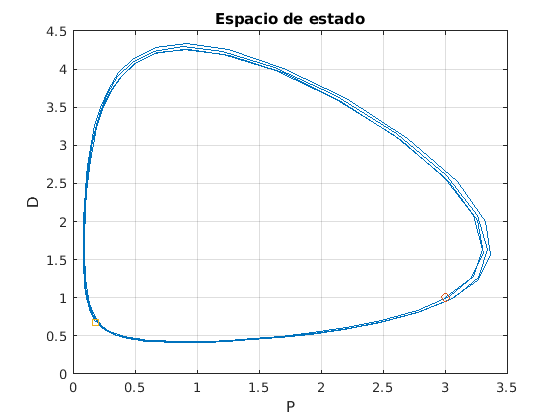

figure
plot(x(:,1),x(:,2))
hold on
plot(x(1,1),x(1,2),'o')
plot(x(end,1),x(end,2),'s')
xlabel('P')
ylabel('D')
title('Espacio de estado')
grid on

**Análisis 1 y 2: **el modelo de presa depredador representa la dinámica oscilatoria en un ecosistema, donde al aumentar la población de depredadores, las presas comienzan a disminuir. Luego, llega un punto donde las presas son tan bajas que los depredadores se ven afectados y su población desciende. Al disminuir la cantidad de depredadores, las presas comienzan a aumentar, haciendo que la dinámica se repita. 

Por lo tanto, obtenemos procesos oscilatorios que resultan en trayectorias de estado que giran en torno a un valor de presas y depredadores, que en este caso serían aproximadamente $D=2$ y $P=1.5$.

#### 3. Obtener el espacio y trayectorias de estado con un aumento en $D(0)$ y usando al menos 5 valores. Analizar el resultado.

Observar el efecto de aumentar $D(0)$ en la pérdida del ciclo ecológico (cercanía a $P = 0$)

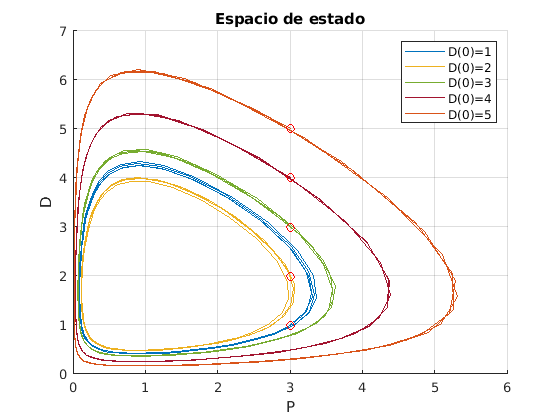

syms P(t) D(t)
alfa = 2; beta = 1.2; delta = 1; gamma = 0.9;           %Parámetros del modelo
f1 = alfa*P - beta*P*D; f2 = delta*P*D - gamma*D;       %Parte derecha de la ecuación de estado: x' = f(x)
f = odeFunction([f1 f2],[P D]);                         %Ecuación de estado en una forma para ser resuelta numéricamente
Ts = 0.1;                                               %Paso de la solución numérica (probar con diferentes valores)
tmin = 0;                                               %Siempre debe ser mayor o igual que cero
tmax = 20;                                              %Tiempo máximo de la simulación
tspan = tmin:Ts:tmax;                                   %Intervalo de tiempo para graficar

P0 = 3;
D0 = [1,2,3,4,5];                                       %Cambio de D(0)
figure
for D0_iter = D0
    hold on
    ci = [P0 D0_iter];
    [t,x] = ode45(f,tspan,ci);
    plot(x(:,1),x(:,2))
    plot(x(1,1),x(1,2),'ro')
end
xlabel('P')
ylabel('D')
title('Espacio de estado')
legend({'D(0)=1','','D(0)=2','','D(0)=3','','D(0)=4','','D(0)=5'})
grid on
hold off % Para no afectar el siguiente gráfico

#### 4. Obtener el espacio y trayectorias de estado con una disminución en $P(0)$ y usando al menos 5 valores. Analizar el resultado.

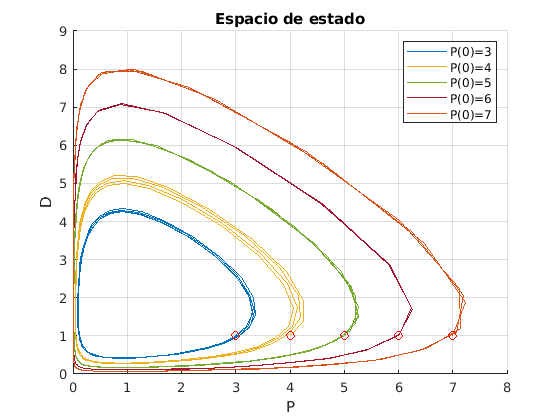

syms P(t) D(t)
alfa = 2; beta = 1.2; delta = 1; gamma = 0.9;           %Parámetros del modelo
f1 = alfa*P - beta*P*D; f2 = delta*P*D - gamma*D;       %Parte derecha de la ecuación de estado: x' = f(x)
f = odeFunction([f1 f2],[P D]);                         %Ecuación de estado en una forma para ser resuelta numéricamente
Ts = 0.1;                                               %Paso de la solución numérica (probar con diferentes valores)
tmin = 0;                                               %Siempre debe ser mayor o igual que cero
tmax = 20;                                              %Tiempo máximo de la simulación
tspan = tmin:Ts:tmax;                                   %Intervalo de tiempo para graficar

D0 = 1;
P0 = [3,4,5,6,7];                                       %Cambio de P(0)
figure
for P0_iter = P0
    hold on
    ci = [P0_iter D0];
    [t,x] = ode45(f,tspan,ci);
    plot(x(:,1),x(:,2))
    plot(x(1,1),x(1,2),'ro')
end
grid on
hold off                                               %Para no afectar el siguiente gráfico
xlabel('P')
ylabel('D')
title('Espacio de estado')
legend({'P(0)=3','','P(0)=4','','P(0)=5','','P(0)=6','','P(0)=7'})

**Análisis del punto 3 y 4: **Al variar las condiciones iniciales, bien sea de presas o depredadores, el equilibrio del modelo no cambia, es decir, el punto central donde las poblaciones oscilan. En este caso,  se puede identificar visualmente que el modelo puede oscilar entre 2 depredadores y 1.5 presas. Al Cambiar las condiciones iniciales, afectamos el tamaño final de las oscilaciones del sistema, con $P(0)=7$ las presas pueden llegar a 7 y los depredadores a 8. 

#### **5. Obtener el espacio y trayectorias de estado con un aumento de **$\beta$** y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. Analizar el resultado.	**

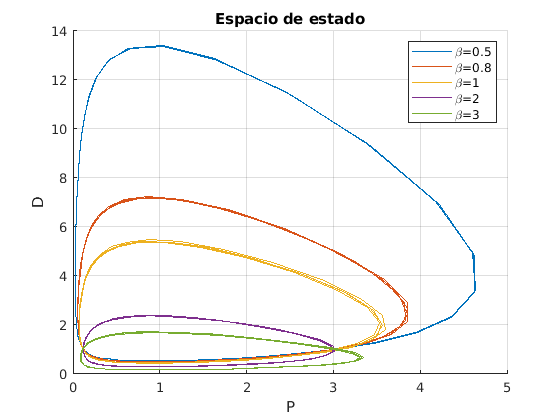

syms P(t) D(t)
alfa = 2; delta = 1; gamma = 0.9;                                   %Parámetros del modelo 
beta = [0.5 0.8 1 2 3];                                             %Variacion de beta
Ts = 0.1;                                                           %Paso de la solución numérica (probar con diferentes valores)
tmin = 0;                                                           %Siempre debe ser mayor o igual que cero
tmax = 20;                                                          %Tiempo máximo de la simulación
tspan = tmin:Ts:tmax;                                               %Intervalo de tiempo para graficar

ci = [3 1];                                       
figure
for beta_iter = beta
    f1 = alfa*P - beta_iter*P*D; f2 = delta*P*D - gamma*D;          %Parte derecha de la ecuación de estado: x' = f(x)
    f = odeFunction([f1 f2],[P D]);                                 %Ecuación de estado en una forma para ser resuelta numéricamente
    hold on
    [t,x] = ode45(f,tspan,ci);
    plot(x(:,1),x(:,2))
end
grid on
hold off                                                            %Para no afectar el siguiente gráfico
xlabel('P')
ylabel('D')
title('Espacio de estado')
legend({'\beta=0.5','\beta=0.8','\beta=1','\beta=2','\beta=3'})

**Análisis: **el parámetro $\beta$ representa las interacciones exitosas de las presas con los depredadores. Al aumentar este parámetro, pero dejar constante el valor de $\delta$, ocaciona que las presas se vean mas afectadas por la acción de los depredadores pero sin que estos últimos aumenten su población. Esto hace que el equilibrio del modelo se desplace sin beneficiar a las presas ni a los depredadores, ambas poblaciones se ven menguadas en cantidad al aumentar $\beta$.

#### **6. Obtener el espacio y trayectorias de estado con un aumento de **$\gamma$** y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. Analizar el resultado.**

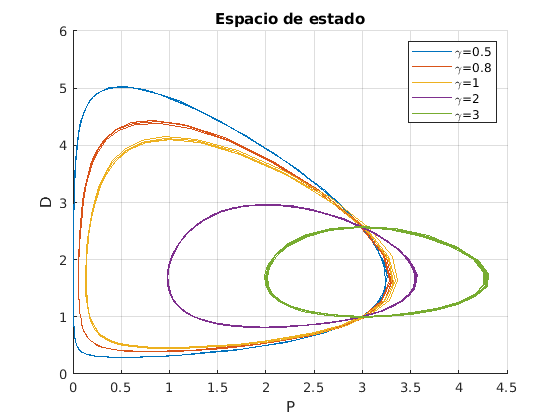

syms P(t) D(t)
alfa = 2; delta = 1; beta = 1.2;                                    %Parámetros del modelo 
gamma = [0.5 0.8 1 2 3];                                            %Variacion de gamma
Ts = 0.1;                                                           %Paso de la solución numérica (probar con diferentes valores)
tmin = 0;                                                           %Siempre debe ser mayor o igual que cero
tmax = 20;                                                          %Tiempo máximo de la simulación
tspan = tmin:Ts:tmax;                                               %Intervalo de tiempo para graficar

ci = [3 1];                                       
figure
for gamma_iter = gamma
    f1 = alfa*P - beta*P*D; f2 = delta*P*D - gamma_iter*D;          %Parte derecha de la ecuación de estado: x' = f(x)
    f = odeFunction([f1 f2],[P D]);                                 %Ecuación de estado en una forma para ser resuelta numéricamente
    hold on
    [t,x] = ode45(f,tspan,ci);
    plot(x(:,1),x(:,2))
end
grid on
hold off                                                            %Para no afectar el siguiente gráfico
xlabel('P')
ylabel('D')
title('Espacio de estado')
legend({'\gamma=0.5','\gamma=0.8','\gamma=1','\gamma=2','\gamma=3'})

**Análisis: **el parámetro $\gamma$ representa la mortalidad de los depredadores. Al aumentarla podemos observar como las trayectorias de estado se desplazan en el eje$x$, haciendo que pueda aparecer una mayor cantidad de presas. Por ejemplo, con $\gamma = 3$ la población de presas puede oscilar entre 2 y 4.4, mientras que con valores mas bajo ($\gamma = 0.5$) la población de las presas no supera 3.3. Ahora, en el caso de los depredadores, las trayectorias de estado se encogen  en sentido del eje $y$ haciendo que la población de depredadores alcance menores cantidades de individuos. Por ejemplo, para $\gamma = 0.5$ se tiene una población máxima de 5, mientras que con $\gamma = 3$ se llega a un máximo de 2.5.

En este caso, el equilibrio se desplaza beneficiando las presas.

Un cambio en el parámetro $\gamma$ se puede relacionar con la cacería de depredadores en una zona protegida, donde es de vital importancia aumentar la población de presas. 